# Bilan macroscopique sur un champ inhomogène

clc
clear all
close all

## Chargement des données

load Fields

Taille du domaine

Lx = 1e-2;
Ly = 1e-2;
b  = 1.0;
dx = x(2) - x(1);
dy = y(2) - y(1);
nx = length(x);
ny = length(y);

Paramètres physiques

rho = 1.0e3;
mu = 1.0e-1;
nu = mu/rho;


Figures

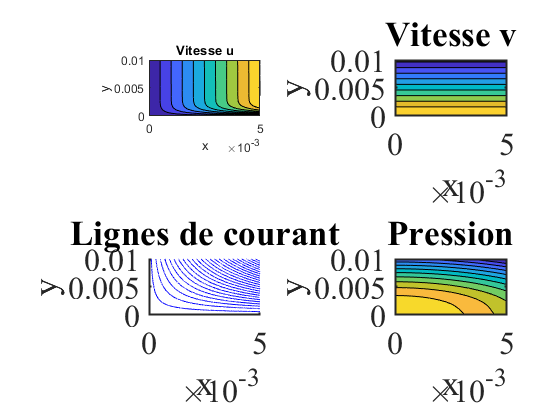

figure(1)
subplot(2,2,1)
contourf(x,y,u')
xlabel('x')
ylabel('y')
title('Vitesse u') 
% % % % % set(gca,'fontsize',24,'fontname','times','linewidth',1.5)

subplot(2,2,2)
contourf(x,y,v')
xlabel('x')
ylabel('y')
title('Vitesse v') 
set(gca,'fontsize',24,'fontname','times','linewidth',1.5)

subplot(2,2,3)
streamline(x,y,u',v',linspace(-Lx/2,Lx/2,50),Ly*ones(1,50))
xlabel('x')
ylabel('y')
title('Lignes de courant') 
set(gca,'fontsize',24,'fontname','times','linewidth',1.5)

subplot(2,2,4)
contourf(x,y,p')
xlabel('x')
ylabel('y')
title('Pression')
set(gca,'fontsize',24,'fontname','times','linewidth',1.5)

## Bilan macroscopique de masse

### Question 1.

delta_m=trapz(x,v(:,end),1)+trapz(y,u(end,:))

delta_m = -3.2435e-07

### Question 2

duyB=(u(:,2)-u(:,1))./dy;
dvxB=([v(2:end,1);0]-[0;v(1:end-1,1)])./dx;
dvyB=(v(:,2)-v(:,1))./dy;
Fx=-trapz(x,-mu.*duyB-mu.*dvxB)

Fx = 0.1529

Fy=-trapz(x,+p(:,1)-2*mu*dvyB)

Fy = 0.2071

### Question 3

duyT=(u(:,end)-u(:,end-1))./dy;
dvxT=([v(2:end,end);0]-[0;v(1:end-1,end)])./dx;
dvyT=(v(:,end)-v(:,end-1))./dy;

duyL=([u(1,2:end),0]-[0,u(1,1:end-1)])./dy;
dvxL=(v(2,:)-v(1,:))./dx;
duxL=(u(2,:)-u(1,:))./dx;

duyR=([u(end,2:end),0]-[0,u(end,1:end-1)])./dy;
dvxR=(v(end,:)-v(end-1,:))./dx;
duxR=(u(end,:)-u(end-1,:))./dx;

Fx0=-trapz(x,rho*u(:,end).*v(:,end))-trapz(y,rho*u(end,:).^2)+trapz(y,-2*mu*duxL+p(1,:))+trapz(x,+mu.*duyT+mu.*dvxT)+trapz(y,+2*mu*duxR-p(end,:))

Fx0 = 0.1541

Fy0=-trapz(x,rho*v(:,end).*v(:,end))-trapz(y,rho*u(end,:).*v(end,:))+trapz(y,-mu*duyL-mu*dvxL)+trapz(x,2*mu*dvyT-p(:,end))+trapz(y,+mu*duyR+mu*dvxR)

Fy0 = 0.2327

### Question 4

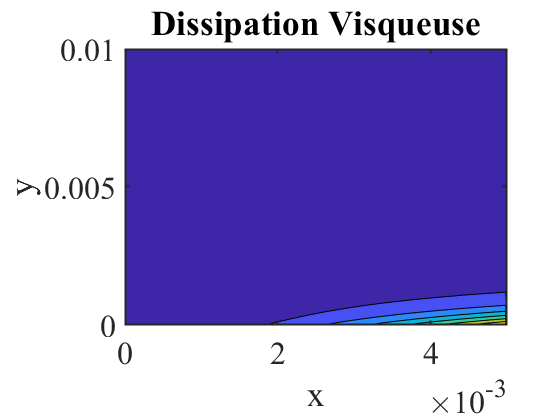

Ev_field = zeros(nx,ny);
for i=1:nx-1
    for j=1:ny-1
        
        d_11 = (u(i+1,j) - u(i,j))/dx;
        d_12 = 0.5*(u(i,j+1) - u(i,j))/dy + (v(i+1,j) - v(i,j))/dx;
        d_13 = 0;
        d_21 = d_12;
        d_22 = (v(i,j+1) - v(i,j))/dy;
        d_23 = 0;
        d_31 = 0;
        d_32 = 0;
        d_33 = 0;
        
        dijdij = d_11^2 + d_12^2 + d_13^2 + d_21^2 + d_22^2 + d_23^2 + d_31^2 + d_32^2 + d_33^2;
        Ev_field(i,j) = 2*mu*dijdij;
    end
end

figure(2) 
contourf(x,y,Ev_field')
xlabel('x')
ylabel('y')
title('Dissipation Visqueuse')
set(gca,'fontsize',24,'fontname','times','linewidth',1.5)


Ev = b*dx*dy*sum(Ev_field(:))

Ev = 0.2109

### Question 5

int_Emeca_T = b*trapz(x, rho * v(:,ny) .* ( 0.5*(u(:,ny).^2 + v(:,ny).^2) + p(:,ny)/rho));

int_Emeca_R = b*trapz(y, rho * u(nx,:) .* ( 0.5*(u(nx,:).^2 + v(nx,:).^2) + p(nx,:)/rho));

tau_yy_T = 2*mu*( (v(:,ny) - v(:,ny-1))/dy  );
tau_xy_T = mu*( (u(1:nx-1,ny) - u(1:nx-1,ny-1))/dy + (v(2:nx,ny) - v(1:nx-1,ny))/dx );
int_tau_vel_T = b*trapz(x(1:nx-1),tau_xy_T.*u(1:nx-1,ny)) + b*trapz(x,tau_yy_T.*v(:,ny));

tau_xy_L = mu*( (u(1,2:ny) - u(1,1:ny-1))/dy + (v(2,1:ny-1) - v(1,1:ny-1))/dx);
int_tau_vel_L = b*trapz(y(1:ny-1), tau_xy_L.*v(1,1:ny-1));

tau_xy_R = mu*( (u(nx,2:ny) - u(nx,1:ny-1))/dy + (v(nx,1:ny-1) - v(nx-1,1:ny-1))/dx );
tau_xx_R = 2*mu*( (u(nx,:) - u(nx-1,:))/dx );
int_tau_vel_R = b*trapz(y, tau_xx_R.*u(nx,:)) + b*trapz(y(1:ny-1),tau_xy_R.*v(nx,1:ny-1));


Ev_new = -int_Emeca_T -int_Emeca_R +int_tau_vel_T -int_tau_vel_L +int_tau_vel_R

Ev_new = 0.2111